%% SCRIPT FOR CALCULATING LIGHT PROPAGATION THROUGH LOW-E GLASS AND L*a*b*
% -------------------------------------------------------------------------
%% GENERAL INPUT DATA
% -------------------------------------------------------------------------
lam = linspace(350, 950, 601);
coating = ["AZO_lowE","Ag_SD3009","AZO_lowE","Ag_SD3009","AZO_lowE"];
materials = ["air",coating,"gls_Kibing","air"];
dlowE =  [30,12.32,70,12.32,30,3e6];
theta = 0; incoh = 6; % incoherent glass is 6th layer 
stack = set_stack( materials, dlowE, lam, theta, incoh );
% -------------------------------------------------------------------------
%% CALCULATING SPECTRA 
% -------------------------------------------------------------------------
[A, T, R] = ATR1D( stack );
% -------------------------------------------------------------------------
%% PLOTTING RESULTS
% -------------------------------------------------------------------------
% spectra
% -------------------------------------------------------------------------
figure(); 
plot(lam,A.sp,lam,T.sp,lam,R.sp);
legend('A','T','R');
xlim([lam(1) lam(end)]); ylim([0 1]);
xlabel('wavelength, nm'); ylabel('ATR');

% -------------------------------------------------------------------------
% colors
% -------------------------------------------------------------------------
% reflectance
[L,a,b] = cielab(lam,R.sp);
figure();
fprintf('Reflectance; L*=%.2f, a*=%.2f, b*=%.2f',L,a,b);

Reflectance; L*=28.85, a*=12.43, b*=-4.24

imshow(lab2rgb(reshape([L, a, b],[1,1,3])),'InitialMagnification',30000);

% transmittance
[L,a,b] = cielab(lam,T.sp);
figure();
fprintf('Transmittance; L*=%.2f, a*=%.2f, b*=%.2f',L,a,b);

Transmittance; L*=91.40, a*=3.98, b*=8.89

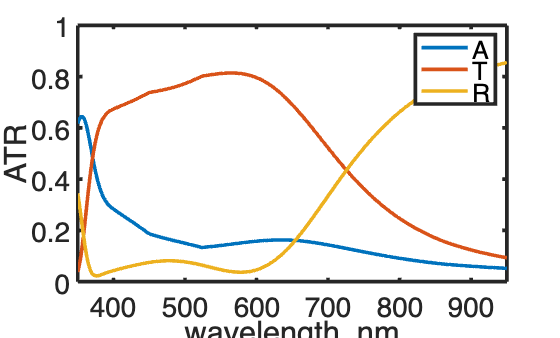

imshow(lab2rgb(reshape([L, a, b],[1,1,3])),'InitialMagnification',30000);